Passo: 1     Residuo:3.5415794044e-05    Residuo:8.1720313077e-06
Passo: 2     Residuo:3.5403218694e-05    Residuo:8.1680007672e-06
Passo: 3     Residuo:3.5390618975e-05    Residuo:8.1639702803e-06
Passo: 4     Residuo:3.5377995010e-05    Residuo:8.1599398615e-06
Passo: 5     Residuo:3.5365346920e-05    Residuo:8.1559095254e-06
Passo: 6     Residuo:3.5352674821e-05    Residuo:8.1518793038e-06
Passo: 7     Residuo:3.5339978826e-05    Residuo:8.1478492569e-06
Passo: 8     Residuo:3.5327259046e-05    Residuo:8.1438194795e-06
Passo: 9     Residuo:3.5314515590e-05    Residuo:8.1397901037e-06
Passo: 10     Residuo:3.5301748563e-05    Residuo:8.1357612991e-06
Passo: 11     Residuo:3.5288958070e-05    Residuo:8.1317332707e-06
Passo: 12     Residuo:3.5276144211e-05    Residuo:8.1277062564e-06
Passo: 13     Residuo:3.5263307087e-05    Residuo:8.1236805233e-06
Passo: 14     Residuo:3.5250446797e-05    Residuo:8.1196563635e-06
Passo: 15     Residuo:3.5237563435e-05    Residuo:8.1156340900e-06
Pass

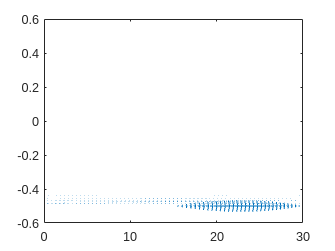

% Obtendo u e v da solução original
% Para a nova solução ser válida, o resultado deve
% ser pelo menos próximo desse.
cavidade

u_original = u;
v_original = v;

nx = 64;
ny = 64;
nt = 100000;
Re = 100;
T = 100;

[results, performanceInfo] = cavidadeFunction(nx, ny, nt, Re, T);
quiver(results.x, results.y, results.u, results.v);

disp(performanceInfo);

    convergence: 1
    nIterations: 5111
       tElapsed: 38.291204000000000



% Verifica se u e v são ou próximos do u e v originais
disp(sum(sum((abs(results.u - u_original)))));

     0



disp(sum(sum((abs(results.v - v_original)))));

     2.941512492187827e-17

